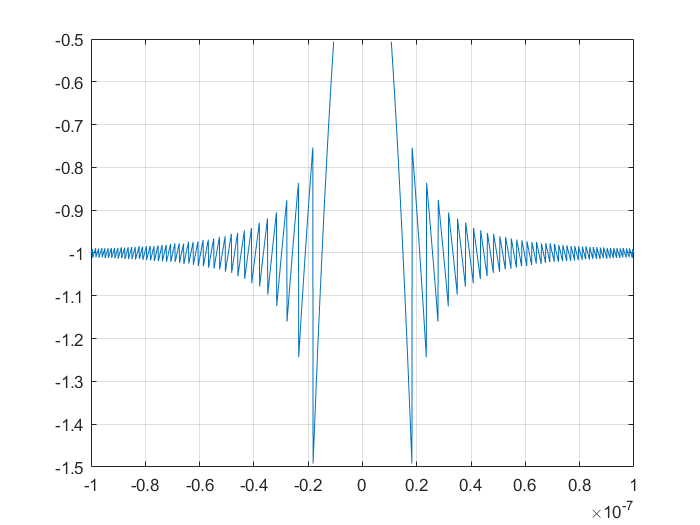

f = @(x) x^2 / (cos(sin(x))^2 - 1);

x = -10^-7:10^-10:10^-7;
y = arrayfun(f, x);

% Reprezentarea grafica
plot(x, y);
grid on;

Functia, pentru x -> 0, ar trebui sa tinda la -1. Din cauza aritmeticii in virgula flotanta, pentru valori cat mai apropiate de 0, se pare ca se indeparteaza de aceasta valoarea, spre valori cat mai mari. De vina este, probabil, scaderea de sub fractie care duce la operatii de genul impartire la 0+ sau 0-.

syms xs;
f_sym = xs^2 / (cos(sin(xs))^2 - 1);
taylor_series = taylor(f_sym, xs, 'Order', 9)

$$taylor\_series = \frac{16\,{\mathrm{xs}}^{8}}{14175}+\frac{{\mathrm{xs}}^{6}}{945}-\frac{2\,{\mathrm{xs}}^{4}}{15}-\frac{2\,{\mathrm{xs}}^{2}}{3}-1$$

O incercare de rezolvare ar fi pentru valori foarte apropiate de 0, sa folosim aproximarea Taylor in loc de a calcula functia direct.

fb = @aprox_taylor % Apare la finalul documentului

fb = function_handle with value:
    @aprox_taylor


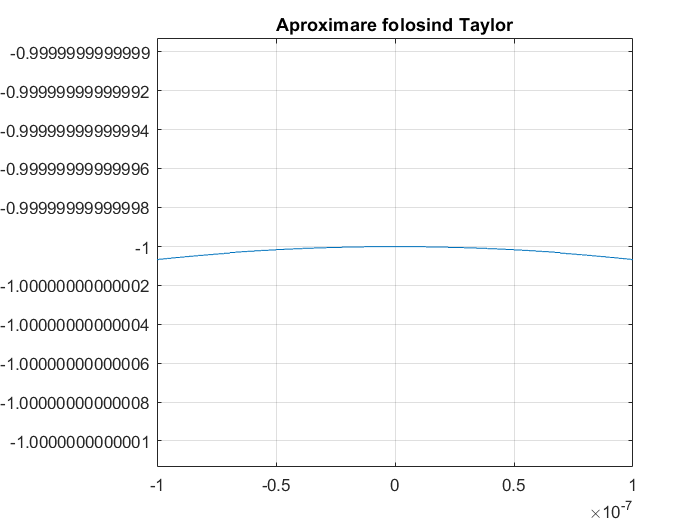

y = arrayfun(fb, x);
plot(x, y);
title('Aproximare folosind Taylor')
grid on;

Folosind aproximarea Taylor, pentru valori apropiate de 0 rezultatul este apropiat de -1, deci aproximarea pare sa fie o solutie buna.

Alta incercare.

cos(sin(x))^2 - 1 = cos(sin(x))^2 - (sin(sin(x))^2 + cos(sin(x))^2) = -sin(sin(x))^2

Functia se poate transforma in  x^2 / (-sin(sin(x))^2);

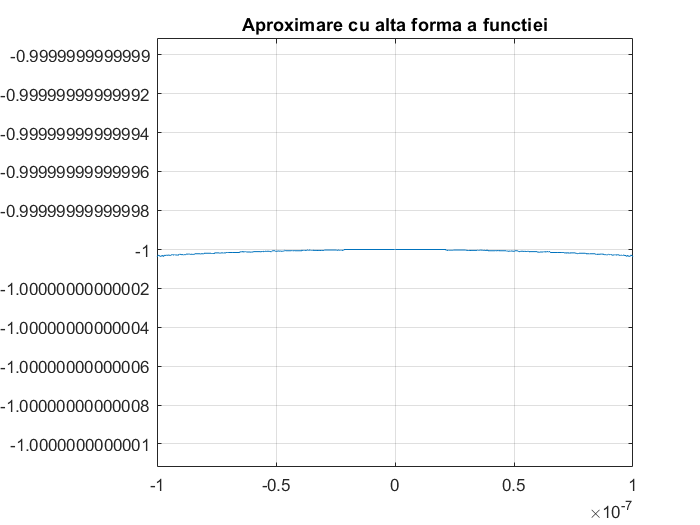

ff = @(x) x^2 / (-(sin(x))^2);
yy = arrayfun(ff, x);
plot(x, yy);
title('Aproximare cu alta forma a functiei')
grid on;

Din grafic reiese ca nu mai exista acea instabilitate cand x -> 0, deci pare sa fie o alternativa buna pentru aritmetica in virgula flotanta.

function rez = aprox_taylor(x)
    if abs(x) < 10^-5
        rez = -1 - 2*x^2/3 - 2*x^4/15 + x^6/945 + 16*x^8/14175;
    else
        rez = x^2 / (cos(sin(x))^2 - 1);
    end
end